## Assignment 4

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

Tristan de le Cruz Hachiles (405541)

% Class Objects
OM = OrbitManeuver;
warning('off','all')

## Task 1: Special Maneuver: Phasing

Below we calculate the total detla_v for a phasing maneuver from inclined LEO orbit to GEO using a phasing orbit to time the interception. First, we only perform an inclination burn when intercepting the target and in the second subtask, we split the inclination burn before and after the transfer.

% Constants and definition of LEO and GEO orbit
mu_earth          = 398600.440;            % km³/s²
Re_earth          = 6371;                  % km
% Interceptor LEO
h_leo       = 200;                   % km
a_leo       = h_leo + Re_earth;            % km
i_leo       = deg2rad(22.5);         % rad
RAAN_leo    = deg2rad(40);           % rad
u_t0        = deg2rad(17);           % rad

% Target GEO
h_geo       = 35786;                 % km
a_geo       = Re_earth + h_geo;            % km
lambda_t0   = deg2rad(200);          % rad


### Task 1a)

% Noncoplanar phasing maneuver. Calculate deltaV and trasfer time

% Step1: burn to phasing orbit
omega_geo = sqrt(mu_earth / (a_geo)^3); % rad/s
omega_leo = sqrt(mu_earth / (a_leo)^3); % rad/s

% The transfer time can be calculated from half of the semimajor axis
% of the Hohman transfer orbit (elliptical orbit between LEO and GEO)
a_trans = (a_leo + a_geo) / 2; % km
t_trans = pi * sqrt(a_trans^3 / mu_earth);  % s
alpha_lead = omega_geo * t_trans;  % rad

% Calculate dTheta angle between ut0 and till RAAN. Also calculate Time
dTheta = pi - u_t0; % rad
dT_node = dTheta / omega_leo;  % s

% We want to calculate the new lead angle after the time to node
lambda_tar_1 = lambda_t0 + omega_geo * dT_node; % rad
lambda_int_1 = RAAN_leo + pi; % TODO: rad. 180 because   we are node point RAAN TODO
theta_new = lambda_int_1 - lambda_tar_1; % rad
alpha_new = theta_new + pi; % rad

% Now we determine the phasing orbit to determine it's semi major axis
P_phase = (alpha_new - alpha_lead) / omega_geo; % s

% Calculate semi major axis of phasing orbit
k_int = 1; % Only one revolution till node
a_phase = (mu_earth * (P_phase / (k_int * 2 * pi)) ^ 2 ) ^ (1/3); % km

% Calculate deltaV at Leo to enter phasing orbit
v_leo = sqrt(mu_earth / a_leo); % km
v_geo = sqrt(mu_earth / a_geo); % km
% Use vis-viva equation to calculate velocities
v_peri_phase = sqrt(2 * mu_earth / a_leo - mu_earth / a_phase); % km/s
v_trans1 = sqrt(2 * mu_earth / a_leo - mu_earth / a_trans); % km/s
v_trans2 = sqrt(2 * mu_earth / a_geo - mu_earth / a_trans); % km/s   

% calculate deltaVs
deltaV1 = abs(v_peri_phase - v_leo); % km/s
deltaV2 = abs(v_trans1 - v_peri_phase); % km/s
deltaVi = sqrt(v_geo ^ 2 + v_trans2 ^ 2 - 2 * v_geo * v_trans2  ... 
               * cos(i_leo)); % km/s
deltaV_total = deltaV1 + deltaV2 + deltaVi; % km/s

% total time is time to node + time till phase + transfer time
t_total = dT_node + P_phase + t_trans; % s

disp(['DeltaV to phasing orbit: ', num2str(deltaV1), ' km/s'])

DeltaV to phasing orbit: 2.241 km/s


disp(['DeltaV to transfer orbit: ', num2str(deltaV2), ' km/s'])

DeltaV to transfer orbit: 0.21558 km/s


disp(['DeltaV combined circularazation and inclination change: ', num2str(deltaVi), ' km/s'])

DeltaV combined circularazation and inclination change: 1.7123 km/s


disp(['Total deltaV for non-coplanar phasing maneuver: ', num2str(deltaV_total), ' km/s'])

Total deltaV for non-coplanar phasing maneuver: 4.1689 km/s


disp(['Transfer time for non-coplanar phasing maneuver: ', num2str(t_total), ' s'])

Transfer time for non-coplanar phasing maneuver: 47856.7303 s


### Task 1b)

% Two burn minimimum inclination change at GEO
v_init      = sqrt(2 * mu_earth / a_leo - mu_earth / a_phase)   ; % km/s
v_trans_a   = sqrt(2 * mu_earth / a_leo - mu_earth / a_trans); % km/s
v_final     = sqrt(mu_earth / a_geo); % km/s
v_trans_b   = sqrt(2 * mu_earth / a_geo - mu_earth / a_trans); % km/s

% calculate s-ratio with Lisowski method
factor1 = 1 / i_leo;
factor2 = (v_init * v_trans_a) / (v_final * v_trans_b);

% Liswowski s-ratio
s = factor1 * atan( sin(i_leo) ... 
                    / (factor2 + cos(i_leo)) ); % rad
% s = 0.006319440565421 %

% total deltaV for two burns at GEO
deltaV_first = sqrt(v_init ^ 2 + v_trans1 ^ 2 - 2 * v_init * v_trans1 * cos(s * i_leo)); % km/s
deltaV_second = sqrt(v_final ^ 2 + v_trans2 ^ 2 - 2 * v_final * v_trans2 * cos((1 -s) * i_leo)); % km/s
deltaV_total2 = deltaV1 + deltaV_first + deltaV_second; % km/s
disp(['Total deltaV for two-burn minimum inclination change at GEO: ', num2str(deltaV_total2), ' km/s']);   

Total deltaV for two-burn minimum inclination change at GEO: 4.2137 km/s


## Task 2: High-thrust maneuver using optimization

For the second tasks, we want to use fmincon to optimize the time of transfer instead of using a phasing orbit to intercept the target at the the right time and position. However, this poses some challenges for the orbit design and the type of transfer.

We decided for a one-tangent-burn maneuver to intercept the target on the GEO orbit. Because of circular intital orbit, the tanget burn doesn't have to be performed at apogee or perigee. This gives as a time range between the nodes to peform the transfer and depending on that time of transfer, the interceptor can be closer or less closer to the target when reaching the node on GEO. Once the interceptor reaches the GEO orbit, a circulization and inclination burn is performed.

Important to note it is that the equation for calculating the one-tangent-burn are limited. The angular distance from the current position of the interceptor to the node must not exceed a certain value. Otherwise, one of the transfer velocity becomes complex due to applying the square root for a negative number caused be a low semi major axis of the transfer orbit. 

The plot below shows the acceptable range to perform the transfer for the given orbital heights from the task description.

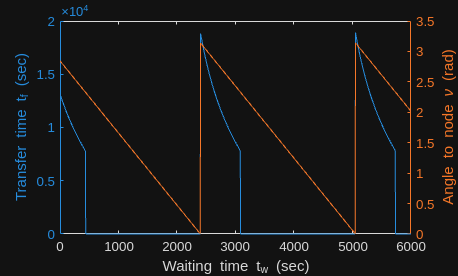

% Determine relevant parameters for transfer orbit (Hohmann Transfer)
r_initial = a_leo;
r_target = a_geo;

% Calculate angular velocity for initial and target orbit
omega_initial = sqrt(mu_earth / r_initial^3);
omega_target = sqrt(mu_earth / r_target^3);

% Angle to node for interceptor
nu = @(t_w) pi - mod(u_t0 + omega_initial * t_w, pi);
x = linspace(1, 6.0E3, 1000);
t_trans = zeros(size(x));  % preallocate
nu_all = zeros(size(x));

for k = 1:length(x)
    [~, ~, ~, ~,~,t_trans(k)] = OM.one_tangent_burn_LEO_GEO(a_leo, a_geo, nu(x(k)), mu_earth);
    nu_all(k) = nu(x(k));
end

figure
yyaxis left
plot(x, t_trans)
ylabel('Transfer time t_f (sec)')
yyaxis right
plot(x, nu_all)
ylabel('Angle to node \nu (rad)')
xlabel('Waiting time t_w (sec)')

The plot above shows that only a real transfer time can be calculated if the angular distance to the node before the transfer is between PI (Hohmann Transfer) and roughly 135 degrees. For other angles, the transfer time is set to zero.

From this plot, the upper and lower bounds for the waiting time for the optimization can be determined. Note that this approach not uses a split factor for the inclination change as the inclination change can only happen when the target has reached at the node on GEO. ´

Below, an optimization for 20 orbtial periods is performed. Relevant optimization parameters are ploted over the number of the half periods after the intital position. 

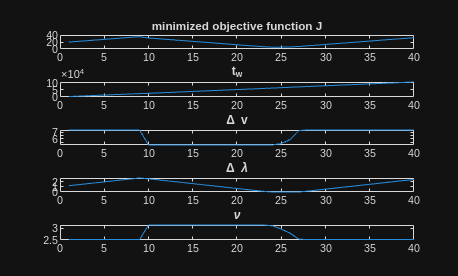

% Optimize t_w to minimize delta_v and delta_lambda
[x_all, t_w_all, delta_v_all, delta_lambda_all, nu_opt_all] = OM.perform_two_impulse_transfer(a_leo, i_leo, RAAN_leo, a_geo, 0, lambda_t0, u_t0, mu_earth, 40);

% Plot 
figure
subplot(5,1,1), plot(x_all), title('minimized objective function J')
subplot(5,1,2), plot(t_w_all), title('t_w')
subplot(5,1,3), plot(delta_v_all), title('\Delta v')
subplot(5,1,4), plot(delta_lambda_all), title('\Delta \lambda')
subplot(5,1,5), plot(nu_opt_all), title('\nu')
subplot(5,1,5), plot(nu_opt_all), title('\nu')

The plot that after a waiting time of 18 hours, the objective function is minimized. The delta v is still low and the distance to the target reaches its minimum. Interesting to see is also that delta v is minimized the the when angular distance to the node is 180 degrees, basically performgin a Hohmann Transfer.

## Task 3: Low-Thrust Maneuver

Below are the initial values given for the assignment converted from Kepler to cartesian. All are bundled in the params struct which will be used for the objective low thrust function passed to the optimizer.

OP = OrbitPropagation;

% Convert Kepplerian initial orbit into cartesian
a = 200 + 6378;     % km
e = 0;              % circular orbit
i = deg2rad(22.5);  % rad
OM= deg2rad(40);    % rad
nu= deg2rad(17);    % rad  
om= deg2rad(0);     % rad

% Information about Target in GEO
lambda_t0 = deg2rad(200); % rad

% Use given initial guess of chaser
params.N     = 12;
params.mu    = 398600.4418;             % km^3/s^2
params.amax  = 1e-7;                    % km/s^2
%params.amax = 0;
params.tw    = 3 * 3600;                % 3 hours (seconds)
params.tLT   = 10 * 86400;              % 10 days (seconds)
params.dt    = 60; % s 
params.nu0   = nu;                      % rad
params.n0    = sqrt(a ^ 3 / params.mu);
[ params.r0, params.v0 ] = OP.convert_kep2car(a, e, i, OM, om, nu, params.mu );

% Target initial information 
params.rGEO = 42164;
params.nGEO = sqrt(params.mu/params.rGEO^3);
params.lambda_t0 = lambda_t0;
params.e_GEO = 0;
params.i_GEO = 0;
params.OM_GEO = 0;
params.om_GEO = 0;

% Penalty weights
params.wa = 1;
params.we = 1;
params.wi = 1;
params.wl = 10;
params.wu = 0;

% Given initial guess for thrust profile
alpha0 =  zeros(params.N,1);         % only tangential burns
delta0 = -0.05 * ones(params.N,1);   % small normal bias (radians)
c0     =  0.8  * ones(params.N,1);   % moderate–high throttle

% Initial Z0
z0 = [delta0; c0]; % Ignore alpha0

% Lower and upper bounds for thrust profile
lb = [ -2/pi * ones(params.N,1);   % beta lower boundary
        0    * ones(params.N,1) ]; % thrust lower boundary

ub = [  2/pi * ones(params.N,1);   % beta upper boundary
        1    * ones(params.N,1) ]; % thrust upper boundary


### Optimization

After letting the optimization run for a bit a converging solution is found with the actual combination of weights. The current weights penalize mainly the delta lambda error and allow maximum effort term. Terms like inclincation, eccentricity and semi major axis are handled equally

costfun = @(z) OP.objective_low_thrust(z, params);

opts = optimoptions('fmincon', ...
    'Display','iter', ...
    'MaxIterations', 100, ...
    'MaxFunctionEvaluations', 20000, ...
    'StepTolerance', 1e-6);

[z_opt, J_opt] = fmincon(costfun, z0, [], [], [], [], lb, ub, [], opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      25    1.258510e+09    0.000e+00    7.289e+05
    1      53    1.257885e+09    0.000e+00    6.407e+05    1.203e-01
    2      79    1.257721e+09    0.000e+00    1.408e+06    5.360e-01
    3     113    1.257652e+09    0.000e+00    1.325e+05    1.524e-02
    4     139    1.257639e+09    0.000e+00    1.384e+05    5.914e-02
    5     172    1.257628e+09    0.000e+00    1.697e+05    3.681e-03
    6     198    1.257624e+09    0.000e+00    1.740e+05    5.453e-02
    7     232    1.257619e+09    0.000e+00    1.552e+05    1.584e-03
    8     258    1.257613e+09    0.000e+00    1.592e+05    2.111e-02
    9     284    1.257603e+09    0.000e+00    2.429e+05    3.770e-01
   10     322    1.257601e+09    0.000e+00    2.047e+05    6.855e-04
   11     348    1.257599e+09    0.000e+00    2.018e+05    9.616e-03
   12     374    1.257513e+09    0.000e+00    3



disp('Optimization finished');

Optimization finished


disp(['Final cost J = ', num2str(J_opt)]);

Final cost J = 1257194463.8529


### Results

 %% ================== RE-PROPAGATE WITH OPTIMAL CONTROLS ==================
% This recomputes the full trajectory (coast + thrust)
[R_opt, V_opt, T_opt] = OP.propagate_low_thrust_history(z_opt, params);

%% ================== SANITY CHECKS ==================
% This is a sanity check, recomputing orbital elements at final time

r_f = R_opt(end,:)';  % Final position [3x1]
v_f = V_opt(end,:)';  % Final velocity [3x1]

% --- Orbital elements from final state ---
[a_f, e_f, inc_f, ~, ~, ~] = OP.convert_car2kep(r_f, v_f, params.mu);

% Display results
disp(['Final semi-major axis [km]: ', num2str(a_f)]);

Final semi-major axis [km]: 6707.7757


disp(['Final eccentricity [-]: ', num2str(e_f)]);

Final eccentricity [-]: 3.9742e-05


disp(['Final inclination [deg]: ', num2str(rad2deg(inc_f))]);

Final inclination [deg]: 22.4999



% --- Final time ---
tf = T_opt(end);

% --- Target final position ---
nu_t = params.lambda_t0 + params.nGEO * tf;

[r_t_final, ~] = OrbitPropagation.convert_kep2car( ...
    params.rGEO, params.e_GEO, ...
    params.i_GEO, params.OM_GEO, ...
    params.om_GEO, nu_t, params.mu);

% --- Miss distance ---
miss_distance = norm(R_opt(end,:) - r_t_final');
disp(['Final miss distance [km]: ', num2str(miss_distance)]);

Final miss distance [km]: 35671.6272



% --- Longitude error ---
lambda_s = atan2(R_opt(end,2), R_opt(end,1));
lambda_t = params.lambda_t0 + params.nGEO * tf;
dLambda = wrapTo2Pi(lambda_s - lambda_t);

disp(['Longitude error [deg]: ', num2str(rad2deg(dLambda))]);

Longitude error [deg]: 8.9045e-05


Because we weighted the longitude error as the highest, the optimizer found a solution with a very small longitude difference between the target and the chaser. Nevertheless that is the only correct value that was minimized: The same solution increases the initial orbit by around 129 km (final semi major axis compared with the initial semi major axis). This results on a final miss distance of 35671 km to GEO. And the inclination seems to be unchanged

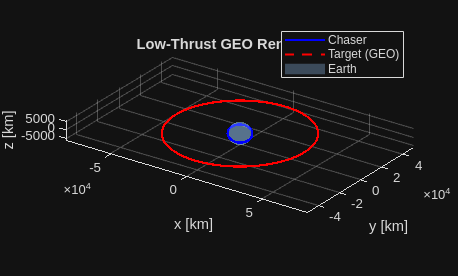


%% ================== PLOT TRAJECTORIES ==================
OP.plot_low_thrust_history(R_opt, T_opt, params);

The trajectory plot shows that the chaser stays on its initial parking orbit plus the 129 km. This shows that the chosen combination of weights is very far from perfect.

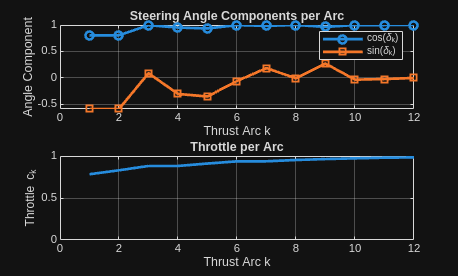

%% =================== PLOT THRUST PROFILE ===================
figure;

delta_opt = z_opt(1:12);
c_opt = z_opt(13:24);
N = length(delta_opt);
arc_idx = 1:N;

% Subplot 1: Cos and Sin of steering angles
subplot(2,1,1);
plot(arc_idx, cos(delta_opt), '-o', 'LineWidth', 2, 'DisplayName', 'cos(\delta_k)');
hold on;
plot(arc_idx, sin(delta_opt), '-s', 'LineWidth', 2, 'DisplayName', 'sin(\delta_k)');
grid on;
xlabel('Thrust Arc k');
ylabel('Angle Component');
title('Steering Angle Components per Arc');
legend;


% Subplot 2: Throttle 
subplot(2,1,2);
plot(arc_idx, c_opt, 'LineWidth', 2);
grid on;
xlabel('Thrust Arc k');
ylabel('Throttle c_k');
title('Throttle per Arc');
ylim([0 1]); % Because c_k ∈ [0,1]

Regarding the thrust profile plot we can also see that the thruster needs to be enabled all the time during the 12 arcs. Regarding the burn direction it is mainly constant in the along track with some fluctuations on the orbit normal parameter. 

Even though the current solution is a physically plausible scenario, it is not an scenario that represents a real low thruster transfer because the GEO orbit is not even contacted. A better combination of weights need to be found.